# BMMO NXE Toolbox - Getting Started

In this document, the most basic steps for using the toolbox are discussed.

## Getting started

To get started using these examples, load the module and its dependent modules using the following command:

module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\BMMO-XY', ...
    '-sameNameControl', 'skip');

Dependent module: ASML toolbox GAAF-Basics                                                         R2021-01-13 (C:\Users\srosenst\AppData\Roaming\MathWorks\MATLAB\ModulesCache\F3D67FBD7F196695\R2021_01_13\Basics)
Including module: BMMO-XY                                                                          R2021-03-03 (C:\Users\srosenst\AppData\Roaming\MathWorks\MATLAB\ModulesCache\C5782B2E64FECDCC\R2021_03_03\BMMO-XY)


## Loading data

The starting point for most analysis is a BMMO NXE or BL3 zip file downloaded from the OTAS or LIS server. This zip contains all the ADELs collected from TwinScan, YieldStar and the OTAS/LIS server that are needed for modeling. For now, we will use the 2 example zips shown below.

zip_dir = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\';
zip_path_bmmo = [zip_dir 'Litho_InSight_Job_ID_14625_TC04.zip'];
zip_path_bl3  = [zip_dir 'Litho_InSight_Job_ID_9447_TC01b.zip'];

When reading in the zip files, the output in the terminal shows the details of ADELs being parsed. In this example we will load the input structure and the sbc recipe that was generated and sent to the TwinScan.

[input_struct_bmmo, ~, sbc_out_bmmo] = bmmo_read_lcp_zip(zip_path_bmmo);

Unzipping \\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\Litho_InSight_Job_ID_14625_TC04.zip
Finding ADELs
Parsing LIS ADELs:
Parsing ADELbmmoOverlayJobReport
Parsing ADELsbcOverlayDriftControlNxe
Reading ADELmetrology
Reading WIDs
    {'AI3AB181MM'}    {'AI3AB222MM'}    {'AI3AB223MM'}    {'AI3AB224MM'}

Mapping WIDs from Job report to ADELmetrology
Applying WEC
Mapping WEC files:
Wafer 1: ADELwaferErrorCorrection_AI3AB181MM_LS_OV_RINT_WEC_AI3AB181MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 2: ADELwaferErrorCorrection_AI3AB222MM_LS_OV_RINT_WEC_AI3AB222MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 3: ADELwaferErrorCorrection_AI3AB223MM_LS_OV_RINT_WEC_AI3AB223MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 4: ADELwaferErrorCorrection_AI3AB224MM_LS_OV_RINT_WEC_AI3AB224MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Subtracting WEC offsets
Reading expinfo
Mark type: BF3u2V
Applying exposure wafer sort order using customer manual mapping and ADELler
     1     2     3     4

Reading 

[input_struct_bl3, ~, sbc_out_bl3] = bmmo_read_lcp_zip(zip_path_bl3);

Unzipping \\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\Litho_InSight_Job_ID_9447_TC01b.zip
Finding ADELs
Parsing LIS ADELs:
Parsing ADELbmmoOverlayJobReport
Parsing ADELsbcOverlayDriftControlNxe
Reading ADELmetrology
Reading WIDs
    {'GFQ4B172MM'}    {'GFQ4B171MM'}    {'GFQ4B170MM'}    {'GFQ4B193MM'}

Mapping WIDs from Job report to ADELmetrology
Applying WEC
Mapping WEC files:
Wafer 1: ADELwaferErrorCorrection_GFQ4B172MM_LS_OV_RINT_WEC_GFQ4B172MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 2: ADELwaferErrorCorrection_GFQ4B171MM_LS_OV_RINT_WEC_GFQ4B171MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 3: ADELwaferErrorCorrection_GFQ4B170MM_LS_OV_RINT_WEC_GFQ4B170MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 4: ADELwaferErrorCorrection_GFQ4B193MM_LS_OV_RINT_WEC_GFQ4B193MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Subtracting WEC offsets
Reading expinfo
Mark type: BF3u2V
Applying exposure wafer sort order using customer manual mapping and ADELler
     1     2     3     4

Read

### Input structure

The input structure to the drift control model is a special instance of the OVL toolbox ml structure:

- it is in single-mark field format

- it contains an info field with extra information needed for modelling

- it contains an expinfo field with exposure information

When creating the input structure from a zip file, it sets the configuration of the model to be the same as the original job the customer ran on OTAS/LIS. Let's look at some of the settings for the 2 example zips:

input_struct_bmmo.info.configuration_data

ans = struct with fields:
                   platform: 'LIS'
    susd_correction_enabled: 0
      KA_correction_enabled: 1
           intraf_actuation: 5


input_struct_bl3.info.configuration_data

ans = struct with fields:
                   platform: 'LIS'
    susd_correction_enabled: 1
      KA_correction_enabled: 1
                  bl3_model: 1
           intraf_actuation: 5


If any of these fields are missing in the input structure, for that setting the model will default to the original BMMO NXE SBC2 configuration as first released on OTAS:

- SUSD correction off

- KA correction off

- BMMO NXE modelling

- Intrafield actuation order = 3

For more details on manipulating the input structure, see **[link to separate page]**

By converting the sigle-mark field input structure into a full field ml structure, we can use all the tools available in the OVL toolbox. This can be done with the following function:

mli_bmmo = bmmo_process_input(input_struct_bmmo);

Once this ml-structure is available, we can for example plot the data using ovl_plot:

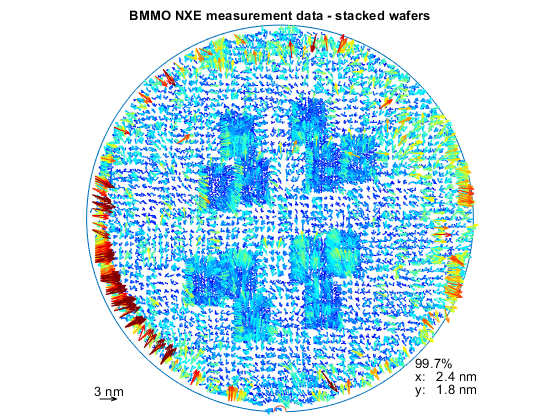

ovl_plot(mli_bmmo, 'vcolor', 'scale', 0, 'title', ...
    'BMMO NXE measurement data - stacked wafers');

### SBC

The sbc structure contains the correction sets as defined in the ADELsbcOverlayDriftControlNxe recipe.

sbc_out_bmmo

sbc_out_bmmo = struct with fields:
       ffp: [1×2 struct]
        MI: [1×1 struct]
        KA: [1×1 struct]
       BAO: [1×2 struct]
    IR2EUV: 0.2055
      SUSD: [1×4 struct]


To see the BAO parameters as sent to the TS:

sbc_out_bmmo.BAO

ans =

1x2 struct array with fields:

     TranslationX      TranslationY       Magnification     AsymMagnification       Rotation         AsymRotation        ExpansionX        ExpansionY       InterfieldRotation       NonOrtho    
    --------------    ---------------    ---------------    -----------------    ---------------    ---------------    --------------    ---------------    ------------------    ---------------
    {[6.2000e-11]}    {[-2.6580e-09]}    {[-1.2400e-07]}    {[-9.3000e-08]}      {[-2.9000e-09]}    {[ 4.9000e-09]}    {[6.0000e-10]}    {[-3.0000e-09]}    {[ 1.3000e-09]}       {[-4.1000e-09]}
    {[3.2420e-09]}    {[-1.8300e-09]}    {[ 1.6800e-07]}    {[ 1.9600e-07]}      {[ 3.9000e-09]}    {[-2.2000e-09]}    {[9.9000e-09]}    {[ 6.6000e-09]}    {[-4.0000e-10]}       {[-8.0000e-10]}



For details on the different ways of applying SBC corrections to data, refer to [bmmo_help_apply_sbc](matlab:open('bmmo_help_apply_sbc'))

## Running the model

With the input structures we can rerun the drift control model offline. In this section we will rerun the model, and compare the sbc generated on LIS/OTAS to the one generated offline in Matlab.

out_bmmo = bmmo_nxe_drift_control_model(input_struct_bmmo)

out_bmmo = struct with fields:
       corr: [1×1 struct]
     report: [1×1 struct]
    invalid: [1×1 struct]


The output structure of the model contains 3 sub-structures:

- corr: a structure containing the sbc correction

- report: a structure containing the KPIs & PIs

- invalid: a structure containing the data points invalidated through outlier removal

Now let's compare the output correction to the one we loaded initially from the zip file, by first rounding the model output to the precision in the ADELsbcOverlayDriftControlNxe recipe:

sbc_mat_bmmo = bmmo_convert_SBC_to_ADELprecision(out_bmmo.corr);

and checking if it's equal to the one loaded:

tolerance = 5e-13;
show_details = 1; 
show_only_NOK_details = 0; 
bmmo_assert_equal(sbc_out_bmmo, sbc_mat_bmmo, tolerance, show_details, show_only_NOK_details)

 OK : (+0.00e+00) (-9.30e-08; -9.30e-08)  in1.BAO(1).AsymMagnification
 OK : (+0.00e+00) (+4.90e-09; +4.90e-09)  in1.BAO(1).AsymRotation
 OK : (+0.00e+00) (+6.00e-10; +6.00e-10)  in1.BAO(1).ExpansionX
 OK : (+0.00e+00) (-3.00e-09; -3.00e-09)  in1.BAO(1).ExpansionY
 OK : (+0.00e+00) (+1.30e-09; +1.30e-09)  in1.BAO(1).InterfieldRotation
 OK : (+0.00e+00) (-1.24e-07; -1.24e-07)  in1.BAO(1).Magnification
 OK : (+0.00e+00) (-4.10e-09; -4.10e-09)  in1.BAO(1).NonOrtho
 OK : (+0.00e+00) (-2.90e-09; -2.90e-09)  in1.BAO(1).Rotation
 OK : (+0.00e+00) (+6.20e-11; +6.20e-11)  in1.BAO(1).TranslationX
 OK : (+0.00e+00) (-2.66e-09; -2.66e-09)  in1.BAO(1).TranslationY
 OK : (+0.00e+00) (+1.96e-07; +1.96e-07)  in1.BAO(2).AsymMagnification
 OK : (+0.00e+00) (-2.20e-09; -2.20e-09)  in1.BAO(2).AsymRotation
 OK : (+0.00e+00) (+9.90e-09; +9.90e-09)  in1.BAO(2).ExpansionX
 OK : (+0.00e+00) (+6.60e-09; +6.60e-09)  in1.BAO(2).ExpansionY
 OK : (+0.00e+00) (-4.00e-10; -4.00e-10)  in1.BAO(2).InterfieldRotation
 OK